## Lecture 9

Matlab 

cov - giver en sample covarians imellem to vektorer (x,Y)

corrcoef - giver korrelationskoefficienten iemmelm to vektorer.

format shortg

**11.2.1**

Diabetes and obesity are serious health concerns in the United States and much of the developed world. Measuring the amount of body fat a person carries is one way to monitor weight control progress, but measuring it accurately involves either expensive X-ray equipment or a pool in which to dunk the subject. Instead body mass index (BMI) is often used as a proxy for body fat because it is easy to measure: $\mathrm{BMI}=\frac{\mathrm{mass}\left(\mathrm{kg}\right)}{{\mathrm{height}\left(m\right)}^2 }=703$. In a study of 250 men at Brigham Young University, both BMI and body fat were measured. Researchers found the following summary statistics:

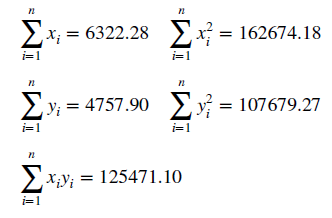

n = 250;
x_sum = 6322.28;
x_sum_squared = 162674.18;
y_sum = 4757.9;
y_sum_squared = 107679.27;
x_times_y = 125471.1;

a. Calculate the least squares estimates of the slope and intercept. Graph the regression line. 


$$y_i =\beta_0 +\beta_1 x_i +\varepsilon_i$$



$$S_{\mathrm{xx}} =162674\ldotp 2-\frac{6322\ldotp {28}^2 }{250}=2789\ldotp 3$$


S_xx = x_sum_squared-(x_sum^2/n)

S_xx =        2789.3



$$S_{\mathrm{xy}} =162674\ldotp 2-\frac{6322\ldotp 28\cdot 4757\ldotp 9}{250}=2789\ldotp 3$$


S_xy = x_times_y-((x_sum*y_sum)/n)

S_xy =          5148



$$\hat{\beta_1 } =\frac{S_{\mathrm{xy}} }{S_{\mathrm{xx}} }=\frac{2789\ldotp 3}{5148}=1\ldotp 8456$$


beta_hat_1 = S_xy/S_xx

beta_hat_1 =        1.8456



$$\hat{\beta_0 } =\bar{y} -\hat{\beta_1 } \bar{x} =4757\ldotp 9-\left(1\ldotp 8456\cdot 6322\ldotp 28\right)$$


x_bar = x_sum/n;
y_bar = y_sum/n;
beta_hat_0 = y_bar - (beta_hat_1*x_bar)

beta_hat_0 =       -27.643



$$\hat{y} =\hat{\beta_0 } +\hat{\beta_1 } x=-27\ldotp 643+1\ldotp 8456x$$



$${\sigma^ˆ }^2 ={\mathrm{MS}}_E =\frac{{\mathrm{SS}}_E }{n-2}=\frac{{\mathrm{SS}}_T -\hat{\beta_1 } \cdot S_{\mathrm{xy}} }{n-2}=\frac{17129-1\ldotp 8456\cdot 5148}{250-2}\;$$



$${\mathrm{SS}}_T =\sum_{i=1}^n y_i^2 -n\cdot {\bar{y} }^2$$


SS_T = y_sum_squared - n*y_bar^2

SS_T =         17129


sigma_hat = (SS_T-(beta_hat_1*S_xy))/(n-2)

sigma_hat =        30.756


x = linspace(15,35)

x =            15       15.202       15.404       15.606       15.808        16.01       16.212       16.414       16.616       16.818        17.02       17.222       17.424       17.626       17.828        18.03       18.232       18.434       18.636       18.838        19.04       19.242       19.444       19.646       19.848       20.051       20.253       20.455       20.657       20.859       21.061       21.263       21.465       21.667       21.869       22.071       22.273       22.475       22.677       22.879       23.081       23.283       23.485       23.687       23.889       24.091       24.293       24.495       24.697       24.899


y_hat = beta_hat_0 + beta_hat_1*x

y_hat =      0.041645       0.4145      0.78736       1.1602       1.5331       1.9059       2.2788       2.6516       3.0245       3.3973       3.7702       4.1431       4.5159       4.8888       5.2616       5.6345       6.0073       6.3802        6.753       7.1259       7.4988       7.8716       8.2445       8.6173       8.9902        9.363       9.7359       10.109       10.482       10.854       11.227         11.6       11.973       12.346       12.719       13.092       13.464       13.837        14.21       14.583       14.956       15.329       15.702       16.074       16.447        16.82       17.193       17.566       17.939       18.312


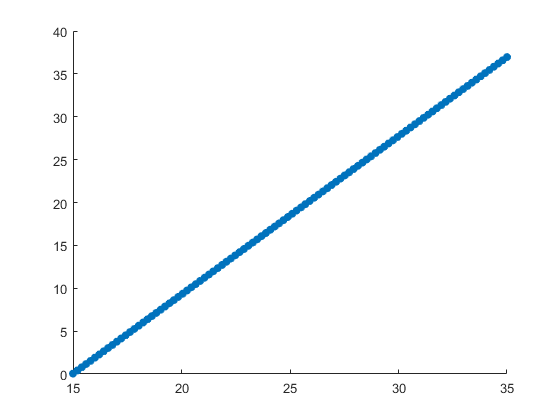

scatter(x,y_hat, 'filled')

b. Use the equation of the fitted line to predict what body fat would be observed, on average, for a man with a BMI of 30.

y_hat_b = beta_hat_0 + beta_hat_1*30

y_hat_b =        27.726


**11.2.3**

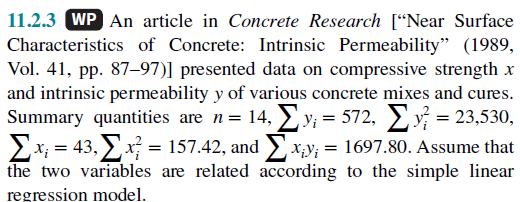

a. Calculate the least squares estimates of the slope and intercept. Estimate $\sigma^{2\;}$. Graph the regression line.

b. Use the equation of the fitted line to predict what permeability would be observed when the compressive strength is $x=4\ldotp 3$.

c. Give a point estimate of the mean permeability when the compressive strength is $x=3\ldotp 7$

d. Suppose that the observed value of permeability at $x=3\ldotp 7$ is $y=46\ldotp 1$. Calculate the value of the corresponding residual.

**11.2.6**

An article in the Journal of Environmental Engineering (1989,Vol. 115(3), pp. 608–619) reported the results of a study on the occurrence of sodium and chloride in surface streams in central Rhode Island. The following data are chloride concentration y (in milligrams per liter) and roadway area in the watershed x (in percentage).

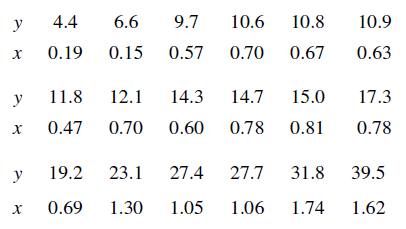

a. Draw a scatter diagram of the data. Does a simple linear regression model seem appropriate here?

b. Fit the simple linear regression model using the method of least squares. Find an estimate of $\sigma^2$.

c. Estimate the mean chloride concentration for a watershed that has 1% roadway area.

d. Find the fitted value corresponding to $x=0\ldotp 47$ and the associated residual.

**11.2.10**

Show that in a simple linear regression model the point (x, y) lies exactly on the least squares regression line.

**11.7.3**

Refer to the compressive strength data in Exercise 11.2.3. Use the summary statistics provided to calculate R2 and provide a practical interpretation of this quantity.

**11.7.5**

Refer to Exercise 11.2.6, which presented data on chloride concentration y and roadway area x. 

a. What proportion of the total variability in chloride concentration is accounted for by the regression model?

b. Plot the residuals versus ̂y and versus x. Interpret these plots.

c. Prepare a normal probability plot of the residuals. Does the normality assumption appear to be satisfied?

**11.9.1**

Determine if the following models are intrinsically linear. If yes, determine the appropriate transformation to generate the linear model.

a. $Y=\beta_0 \cdot x^{\beta {\;}_1 } \cdot \varepsilon$

b. $Y=\frac{3+5x}{x}+\varepsilon$

c. $Y=\beta_0 \cdot \beta_1^x \cdot \varepsilon$

d. $Y=\frac{x}{\beta_0 \cdot x+\beta_1 +x\cdot \;\varepsilon }$

11.9.2

The vapor pressure of water at various temperatures

is in the table below:

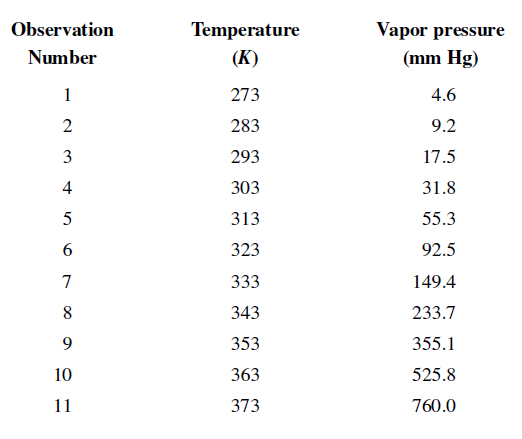

a. Draw a scatter diagram of these data. What type of relationship seems appropriate in relating y to x?

b. Fit a simple linear regression model to these data.

c. Test for significance of regression using $\alpha =0\ldotp 05$. What conclusions can you draw?

d. Plot the residuals from the simple linear regression model versus ̂yi. What do you conclude about model adequacy?

e. The Clausius–Clapeyron relationship states that $\mathrm{ln}\left(P_v \right)\propto -\frac{1}{T}$ where $P_v$ is the vapor pressure of water. Repeat parts (a)–(d) using an appropriate transformation.

SP 10 + 11